% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 9);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Task", "time"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "categorical", "datetime"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Task", "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Var1", "InputFormat", "yyyy-MM-dd HH:mm:ss.SSS", "DatetimeFormat", "preserveinput");
opts = setvaropts(opts, "time", "InputFormat", "yyyy-MM-dd HH:mm:ss.SSS", "DatetimeFormat", "preserveinput");

% Import the data
x01_train_lower_labeled = readtimetable("C:\Users\liken\Desktop\Gait Classifier\Raw_Data\Labeled\01_train_lower_labeled.csv", opts, "RowTimes", "Var1");

% Clear temporary variables
clear opts

% Display results
x01_train_lower_labeled

x01_train_lower_labeled = 118320×8 timetable
             Var1                Var2        Var3        Var4        Var5      Var6        Var7        Task               time          
    _______________________    ________    ________    _________    ______    _______    _________    _______    _______________________

    2024-09-26 12:15:05.690    -0.93091    -0.27808    -0.062988    3.6011     -6.897      -7.6294    bending    2024-09-26 12:15:05.690
    2024-09-26 12:15:05.699     -0.9292    -0.27466    -0.055664    3.7231     -6.897      -7.6294    bending    2024-09-26 12:15:05.699
    2024-09-26 12:15:05.710     -0.9248    -0.271

% Perform basic data analysis
summary(x01_train_lower_labeled);


x01_train_lower_labeled: 118320×8 timetable

Row Times:

    Var1: datetime

Variables:

    Var2: double
    Var3: double
    Var4: double
    Var5: double
    Var6: double
    Var7: double
    Task: categorical (2 categories)
    time: datetime

Statistics for applicable variables and row times:

            NumMissing                Min                        

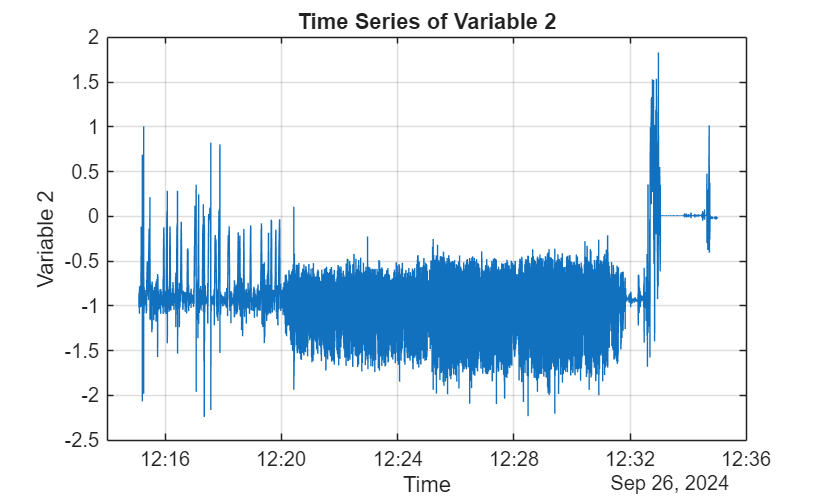

% Visualize the data with a plot
figure;
plot(x01_train_lower_labeled.time, x01_train_lower_labeled.Var2);
xlabel('Time');
ylabel('Variable 2');
title('Time Series of Variable 2');
grid on;

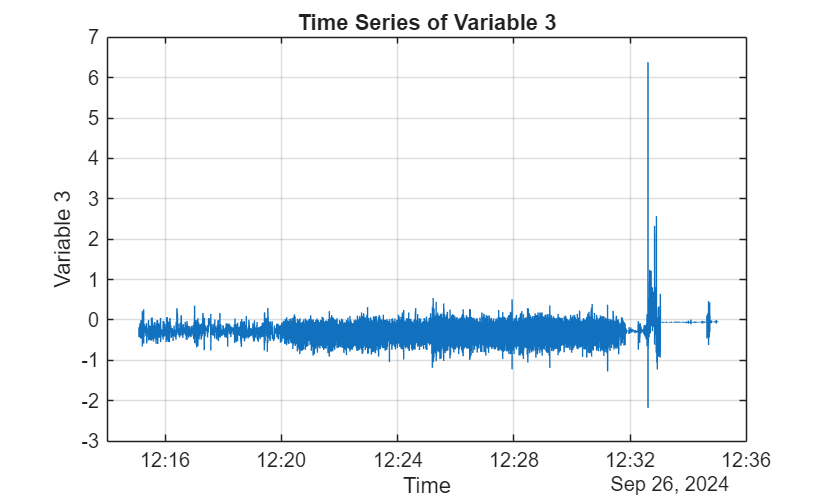

%plot var 3 vs time
% Plot variable 3 against time
figure;
plot(x01_train_lower_labeled.time, x01_train_lower_labeled.Var3);
xlabel('Time');
ylabel('Variable 3');
title('Time Series of Variable 3');
grid on;

%plot var 4 vs time
% Plot variable 4 against time
figure;
plot(x01_train_lower_labeled.time, x01_train_lower_labeled.Var4);
xlabel('Time');
ylabel('Variable 4');
title('Time Series of Variable 4');
grid on;